clear;close all;clc;
load nspeech2.mat;

f=[1.8,2.2];
m=[1,0];
ripple=[0.05,0.005];

[n,fo,mo,w]=firpmord(f,m,ripple,2*pi);
b=firpm(n+3,fo,mo,w);

filterlength = 29

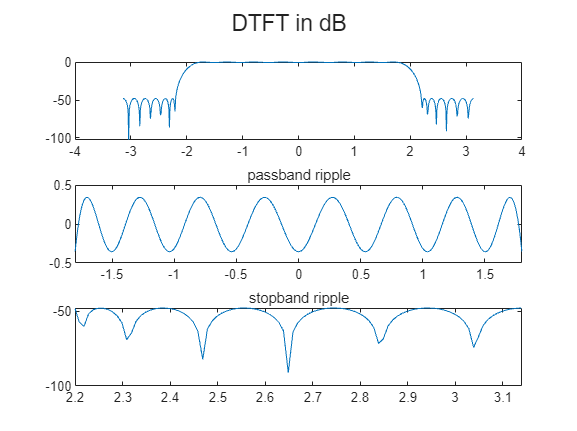

filterlength=n+4
omega_w=-pi:0.01:pi;

z=exp(1i*omega_w);

h_total=b(1);
for k =2:length(b)
    h_total=h_total+b(k).*z.^(-(k-1));
end
mag_h=20*log10(abs(h_total));
% figure;
% sgtitle('DTFT')
% subplot(311);plot(omega_w,abs(h_total));
% subplot(312);plot(omega_w,abs(h_total));xlim([-1.8,1.8]);title('passband ripple');
% subplot(313);plot(omega_w,abs(h_total));xlim([2.2,3.14]);title('stopband ripple');

figure;
sgtitle('DTFT in dB')
subplot(311);plot(omega_w,mag_h);
subplot(312);plot(omega_w,mag_h);xlim([-1.8,1.8]);title('passband ripple');
subplot(313);plot(omega_w,mag_h);xlim([2.2,3.14]);title('stopband ripple');

ripple1= max(abs(h_total(abs(omega_w)<=1.8)))-1

ripple1 = 0.0402

ripple2= max(abs(h_total(abs(omega_w)>=2.2)))

ripple2 = 0.0040

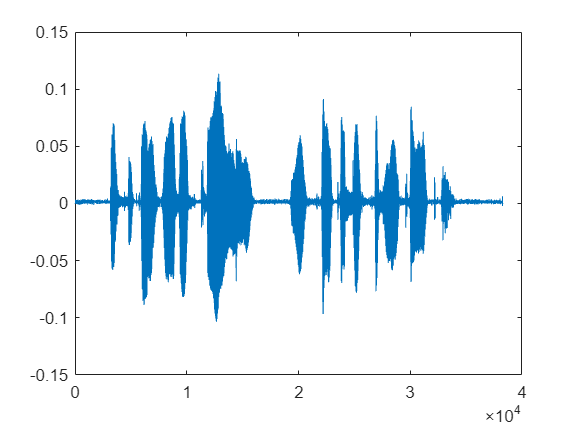

figure;
res=conv(b,nspeech2);
% sound(res);
plot(res)

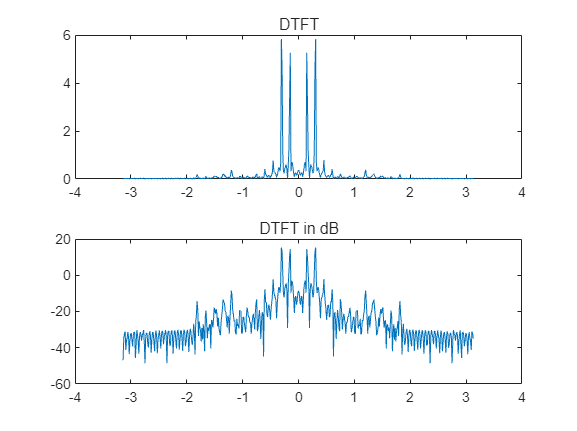

figure
[X,w]=DTFT(res(20001:20400),512);
subplot(211);plot(w,abs(X));title('DTFT');
subplot(212);plot(w,20*log10(abs(X)));title('DTFT in dB');